# Mohammadreza ARani

## Convex Optimization

## 810100511

% Hw 7 --> Q6
clear ;clc ; close all;

% Load Data:
m = 100;
n = 500;

A= rand(m,n) ; 
c= rand(n,1);
x_0 = rand(n,1);

b = A*x_0;




## solve the LP with barrier:



[x_star, Values, gap] = LP_Barrier(A,b,c,x_0);
[xx, yy] = stairs(cumsum(Values(1,:)),Values(2,:));


## Plot:

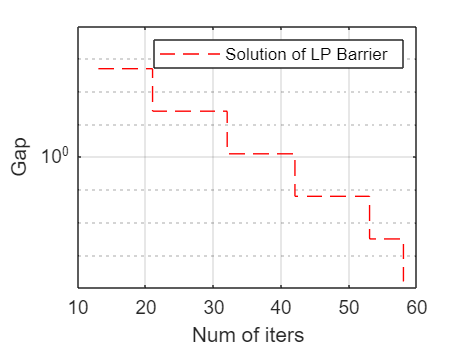


figure()
semilogy(xx,yy,'r--');
xlabel('Num of iters')
ylabel('Gap')
grid on
legend('Solution of LP Barrier')

p_star = c'*x_star;

## Check Versus CVX:

% solve LP using cvx for comparison
cvx_begin
        variable x(n)
            minimize(c'*x)
            subject to
                A*x == b
                x >= 0
cvx_end

 
Calling SDPT3 4.0: 500 variables, 100 equality constraints
------------------------------------------------------------

 num. of constraints = 100
 dim. of linear var  = 500
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.2e+02|3.6e+01|2.4e+06| 5.179399e+04  0.000000e+00| 0:0:00| chol  1  1 
 1|0.972|1.000|1.2e+01|3.0e-01|7.3e+04| 1.575509e+03 -5.551456e+03| 0:0:00| chol  1  1 
 2|1.000|1.000|1.4e-08|3.0e-02|4.8e+03| 1.221327e+02 -4.690140e+03| 0:0:00| chol  1  1 
 3|1.000|0.954|1.1e-09|4.2e-03|2.2e+02| 1.204767e+02 -1.003720e+02| 0:0:00| chol  1  1 
 4|0.948|1.000|6.1e-10|3.0e-04|1.3e+02| 8.225414e+01 -5.0986


disp('Optimal value found by LP_barrier :');

Optimal value found by LP_barrier :


p_star

p_star =   31.854965387543849



disp('Duality Gap from LP_barrier :');

Duality Gap from LP_barrier :


gap

gap =      1.562500000000000e-04



disp('Optimal value found by CVX_MATLAB :');

Optimal value found by CVX_MATLAB :


cvx_optval

cvx_optval =   31.854841088424255



disp("difference between CVX and LP_Barrier : ")

difference between CVX and LP_Barrier : 


disp(abs(p_star-cvx_optval)) % Which is sooo small!

     1.242991195944398e-04



function [x_star, Values, gap] = LP_Barrier(A,b,c,x_0)
% solves standard form LP
% min c'*x
% subject to Ax = b, x >=0;

    T_0 = 1;
    V = 20;
    n = length(x_0);
    t = T_0;
    x = x_0;
    Values = [];


EPSILON = 1e-3; % Duality Gap Stopping condition
    while(1)
        [x_star, V_opt, lambda_hist] = Newton_method_q5(A,b,t*c,x);
        x = x_star;
        gap = n/t;
        Values = [Values [length(lambda_hist); gap]];
            if gap < EPSILON
                break; 
            end
        t = V*t;
    end

end


function [x_star, V_opt, Lambdas, iter] = Newton_method_q5(A,b,c,x_0)


    max_Count = 100;
    m = length(b);
    n = length(x_0);
    x = x_0; 
    Lambdas = [];
    alpha = 0.01;
    beta = 0.5;
    eps = 10^-6;


    if (min(x_0) <= 0) || (norm(A*x_0 - b) > 1e-3) % check feasibility of x_0
        fprintf('Not Feasible');
        V_opt = []; x_star = []; Lambdas=[];
        return;
    end

for iter = 1:max_Count

    H = diag(x.^(-2));
    g = c - x.^(-1);


% Newton step via whole KKT system
        % M = [ H A'; A zeros(m,m)];
        % d = M\[-g; zeros(m,1)];
        % dx = d(1:n);
        % w = d(n+1:end);

    % Newton Step by elimination method
    w = (A*diag(x.^2)*A')\(-A*diag(x.^2)*g);
    dx = -diag(x.^2)*(A'*w + g);
    lambdasqr = -g'*dx;          % dx'*H*dx;
    Lambdas = [Lambdas lambdasqr/2];


    if lambdasqr/2 <= eps 
        break;
    end


    % backtracking line search
    % first bring the point inside the domainTheta
    t = 1; 
    while min(x+t*dx) <= 0
        t = beta*t; 
    end

    % Backtracking line search:
        while c'*(t*dx)-sum(log(x+t*dx))+sum(log(x))-alpha*t*g'*dx> 0
            t = beta*t;
            end
            x = x + t*dx;
 end

    if iter == max_Count % max_Count reached
        disp('Did not Coverged!');
        x_star = []; V_opt = [];
        else
        x_star = x;
        V_opt = w;
    end

end